# Use SVM to achieve character recognition

## 1. Training Data Preparations

Use ImageDataStore to load data

clear
clc

dataset_folder = 'dataset';
imds = imageDatastore(dataset_folder, 'IncludeSubfolders', true, 'LabelSource', 'foldernames');

% Split the dataset into training set and validation set
[imdsTrain, imdsValidation] = splitEachLabel(imds, 0.75, 'randomized');

将图像数据转化为一维的特征向量

% load train and test data from imds
train_data = readall(imdsTrain);
test_data = readall(imdsValidation);

% convert image data to one-dimension vector
train_data = cellfun(@(x) reshape(x, [], 1), train_data, 'UniformOutput', false);
train_data = im2double(cell2mat(train_data')');
test_data = cellfun(@(x) reshape(x, [], 1), test_data, 'UniformOutput', false);
test_data = im2double(cell2mat(test_data')');

## 2. Train SVM Model

tic
SVMModel = fitcecoc(train_data, imdsTrain.Labels);
toc

Elapsed time is 6.361608 seconds.


save('SVMModel.mat', "SVMModel");

### 2.1 cross validation of the model

load('SVMModel.mat')
cv_svm = crossval(SVMModel)

cv_svm =   ClassificationPartitionedECOC
    CrossValidatedModel: 'ECOC'
         PredictorNames: {1×16384 cell}
           ResponseName: 'Y'
        NumObservations: 1337
                  KFold: 10
              Partition: [1×1 cvpartition]
             ClassNames: [0    4    7    8    A    D    H]
         ScoreTransform: 'none'


  Properties, Methods


oosLoss = kfoldLoss(crossval(SVMModel))

oosLoss = 0.0419

## 3. Calculate Accuracy

### 3.1 Accuracy on validation set

load('SVMModel.mat')
% predict on predict set
YPred = predict(SVMModel, test_data);

% calculate accuracy.
accuracy = sum(YPred == imdsValidation.Labels) / length(imdsValidation.Labels);
fprintf('Accuracy: %.2f%%\n', accuracy * 100);

Accuracy: 97.05%


### 3.2. Accuracy on test set

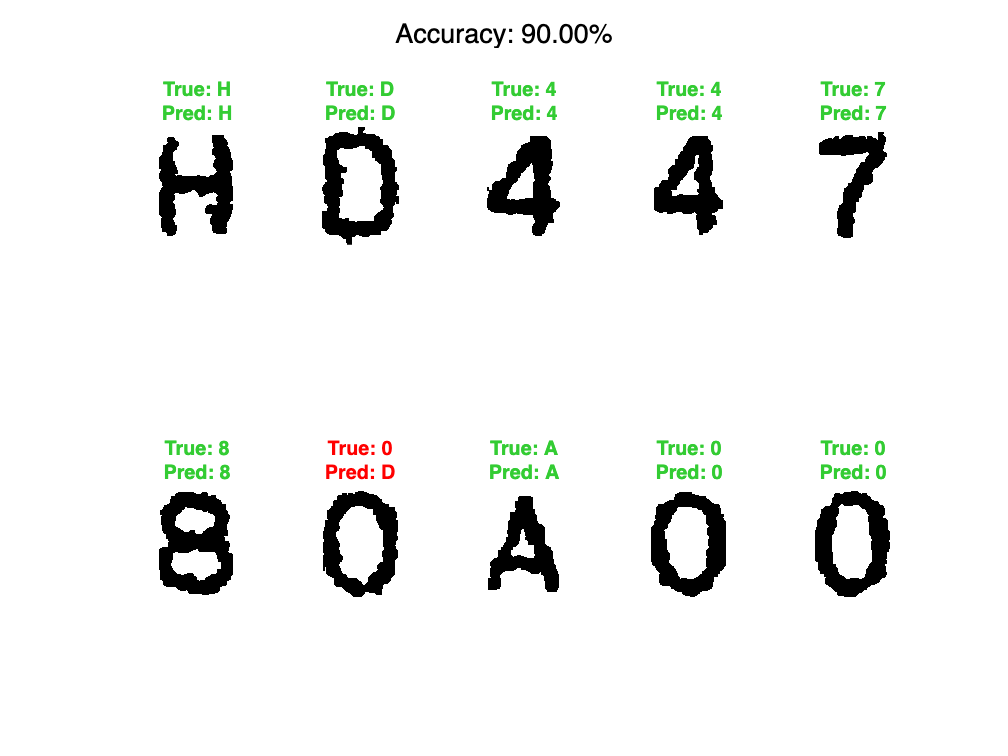

character_folder = 'character';
imdsTest = imageDatastore(character_folder, 'IncludeSubfolders', true);
imdsTest.Labels = categorical(["H","D","4","4","7","8","0","A","0","0"]);

test_data = imdsTest.readall;
test_data = cellfun(@(x) reshape(x, [], 1), test_data, 'UniformOutput', false);
test_data = im2double(cell2mat(test_data')');

test_pred = predict(SVMModel, test_data);
test_accuracy = sum(test_pred == imdsTest.Labels)/numel(imdsTest.Labels);

clf
for i = 1:10
    I = readimage(imdsTest, i);
    True_Label = imdsTest.Labels(i);
    Pred_Label = test_pred(i);
    subplot(2, 5, i);
    imshow(I);
    if True_Label == Pred_Label
        color = [0.2 0.8 0.2];
    else
        color = [1 0 0];
    end
    title({['True: ' char(True_Label)], ['Pred: ' char(Pred_Label)]},'FontSize', 11,'Color', color);
end
sgtitle(sprintf('Accuracy: %.2f%%',100*test_accuracy));